# **Vehicle Dynamics, Yaw Control For Stability and Path Following**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robust Controls 8352 | Ohio State University | 12/15/2022

with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc

Building off of previous work, titled: Lateral Vehicle Dynamics Modeling and Simulation

clc; clear; close all

# Background on The Bicycle Model 

**Single Track Model (Bicycle) (with 3 degrees of freedom)**

Valid for lateral accelerations smaller than 0.3-0.4 g - constant longitudinal vehicle speed and small side slip angle. This model has "lumped" axles and thus only models one front and one rear wheel. 

for a model in the x y plane:  roll is neglected (about x), pitch is neglected (about y) 

longitudinal forces are neglected, but can be added. 

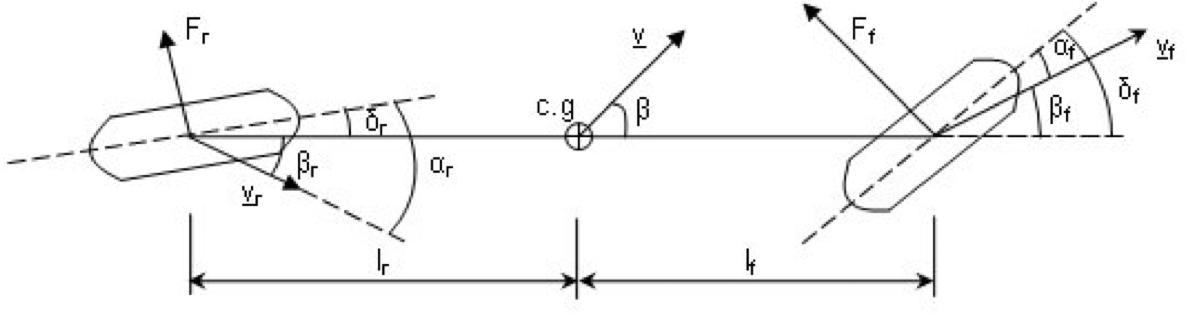

with states described by: Vehicle Side Slip Angle, Beta, Vehicle center of gravity speed, V, and Yaw rate, r.

The model is used in practice as a linearized version which holds speed constant, and thus necessitates different models for different speeds. 

**Understeer** is a vehicle's intentional tendency to turn less sharply than the change in steering wheel input from the driver when at higher steering angles - it is intuitively easy to control so vehicles are designed with an understeer. this understeer occurs as a gradient. During understeering, the side slip angle for the front tires are greater than the rear tires

**Oversteer** is the opposite and is more difficult to control, and hence is not a desirable characteristic. The side slip angle for the rear wheels during oversteering is greater than the rear wheel side slip angle. 

**Yaw Velocity Gain** is used to compare the steering response of vehicles. It is **the ratio of the steady state yaw velocity to the steer angle**. where the steady state yaw velocity Ωz is the ratio of the longitudinal speed to the turning radius R **where yaw velocity gain has units of deg/s/deg (or radians) **

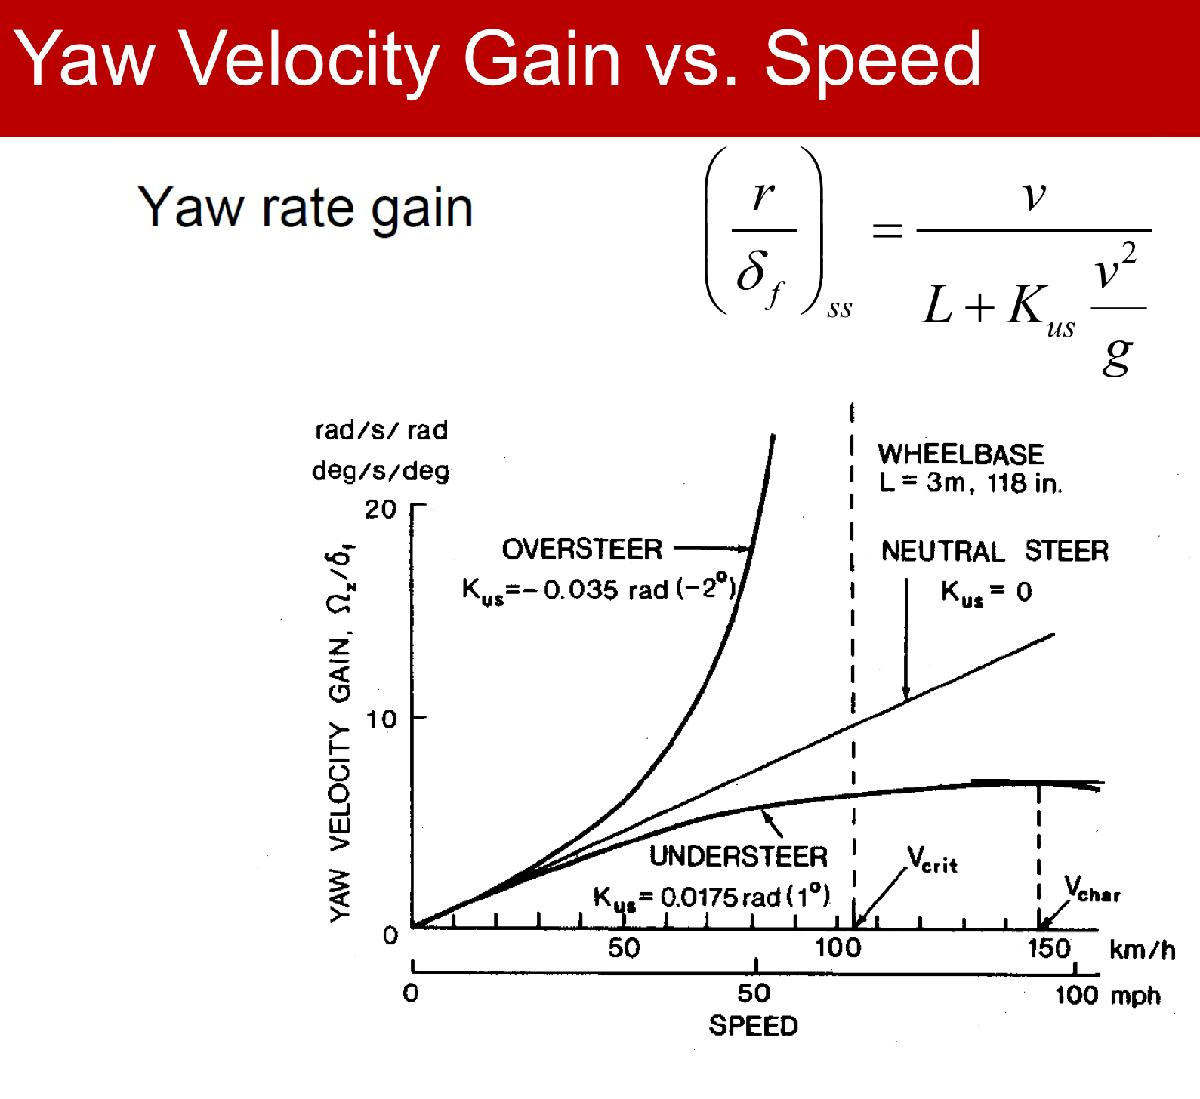

# Vehicle Parameters 

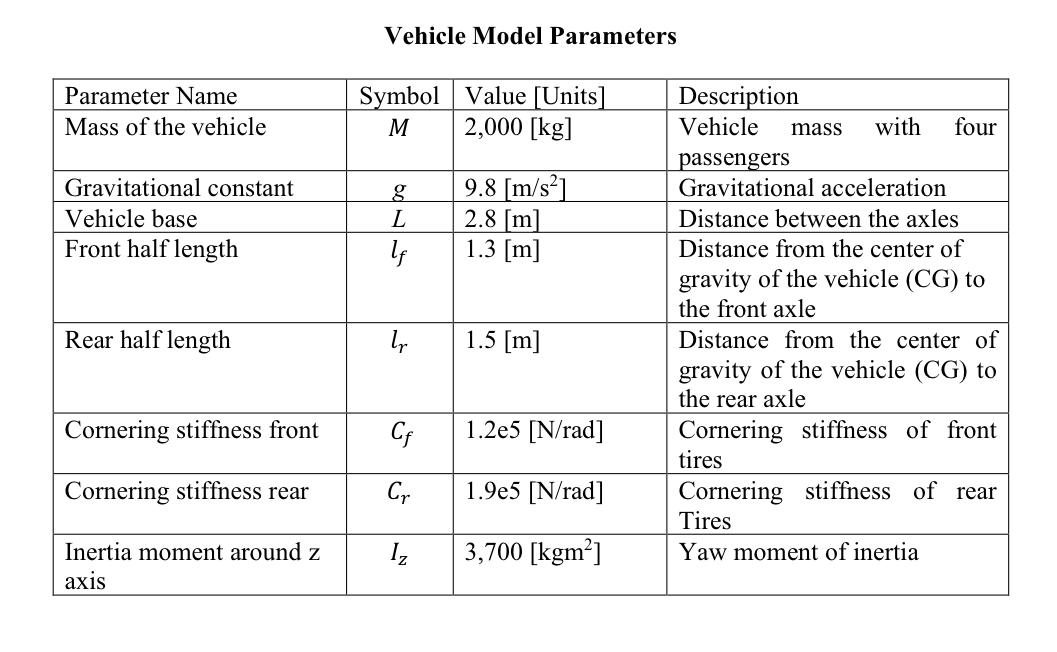

L=2.85; % Distance between the axles [m]
g=9.81; % 
Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
Cf = 3e5; % Cornering Stiffness of Front Tires x2
Cr = 3e5; % Cornering Stiffness of Rear Tires x2
Cs = 1.5e5; % Cornering Stiffness
m = 2000; %Mass of the vehicle [kg]
J = 3700; %Yaw moment of Inertia
mu = 0.7; %Dry coefficient of Friction
R = 0.3; % Wheel radius
Vref = 20; % Constant vehicle velocity.
alphaf = 0.1; % Steering wheel angle rad/sec

%Linear Parameters Calculation
a11 = -(Cr+Cf)/(m*Vref);
a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
a21 = (Lr*Cr-Lf*Cf)/J;
a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
b11 = Cf/(m*Vref);
b12 = Cr/(m*Vref); %delta_r parameter
b21 = Cf*Lf/J;
b22 = Cr*Lr/J; %delta_r parameter
e2 = 1/J; % For yaw moment term

**The Understeer Gradient, Kus can be calculated from**

Kus_vehicle = (Lr/Cf/L - Lf/Cr/L)*m*g

Kus_vehicle = 0.0057

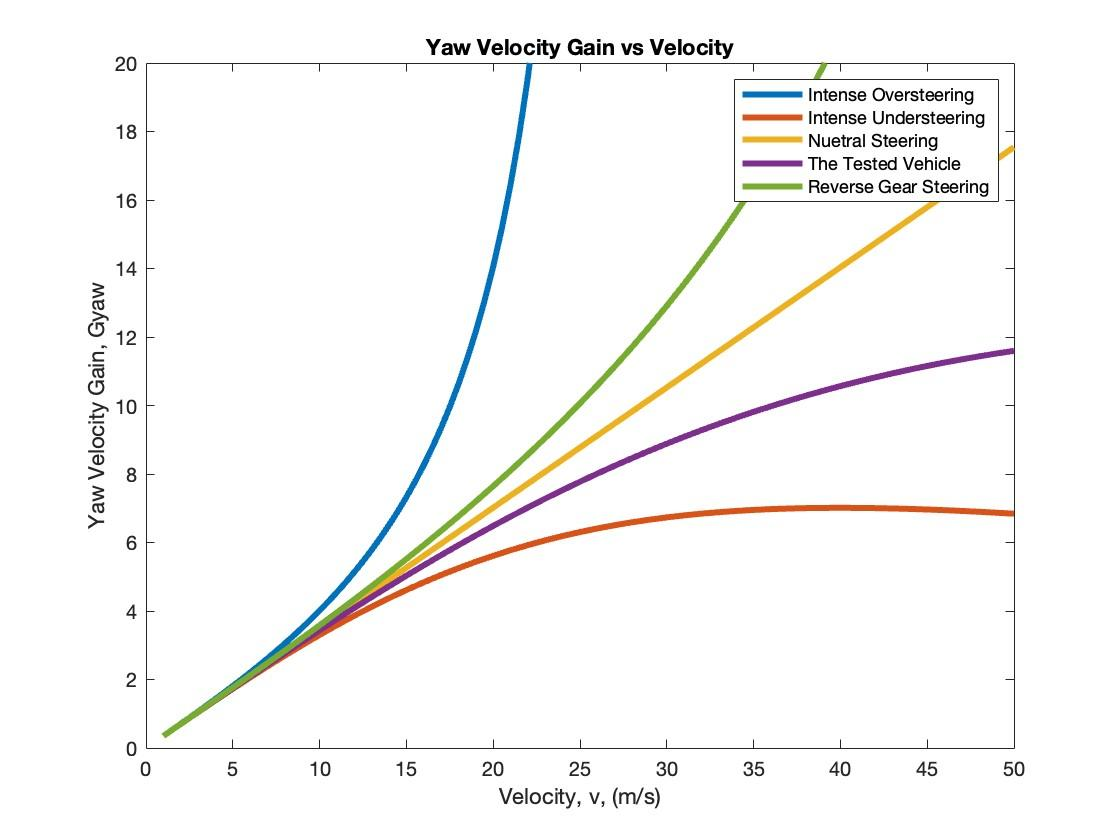

Note that most vehicles are designed to be understeering for ease of control. The test vehicle included. Notice how the reverse gear steering is slightly oversteered, which makes control of reverse gear less intuitive. 

# Path Generation

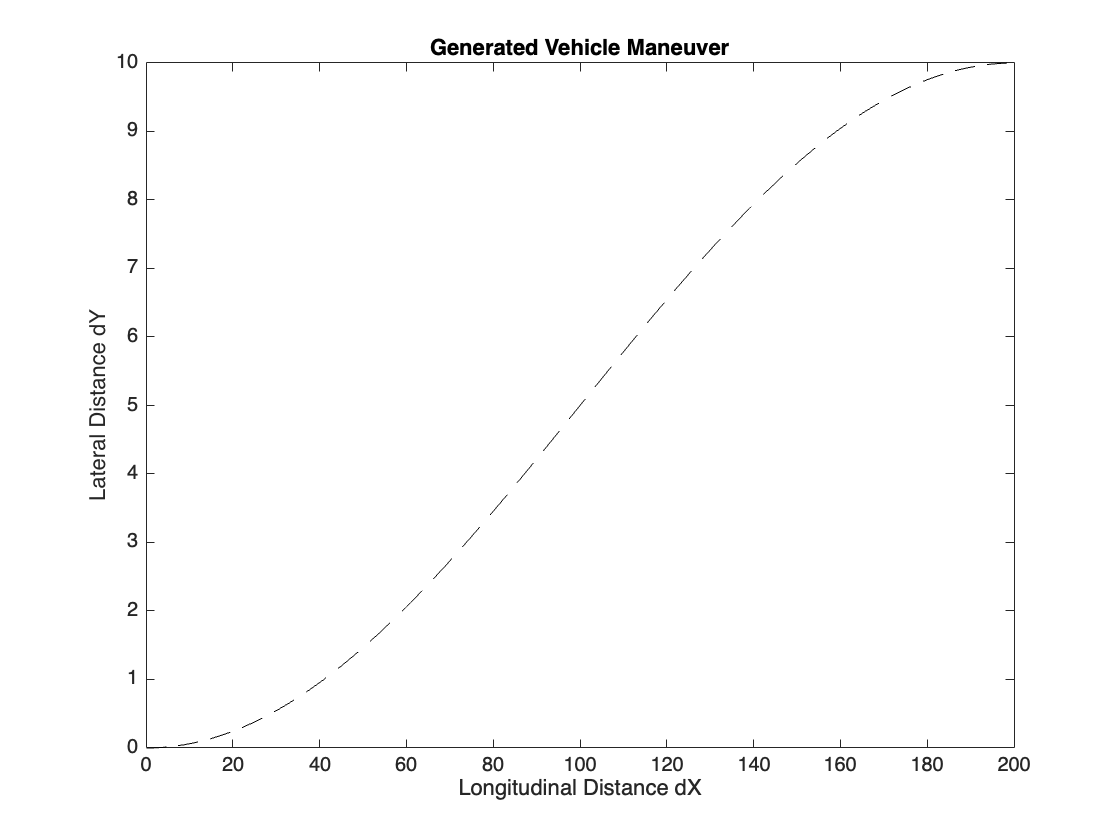

path =          0         0
    0.1000    0.0000
    0.2000    0.0000
    0.3000    0.0001
    0.4000    0.0001
    0.5000    0.0002
    0.6000    0.0002
    0.7000    0.0003
    0.8000    0.0004
    0.9000    0.0005


dX = 200;
dY = 10;
path = getLaneChangePath(dX,dY)

# Path Curvature, Path Length

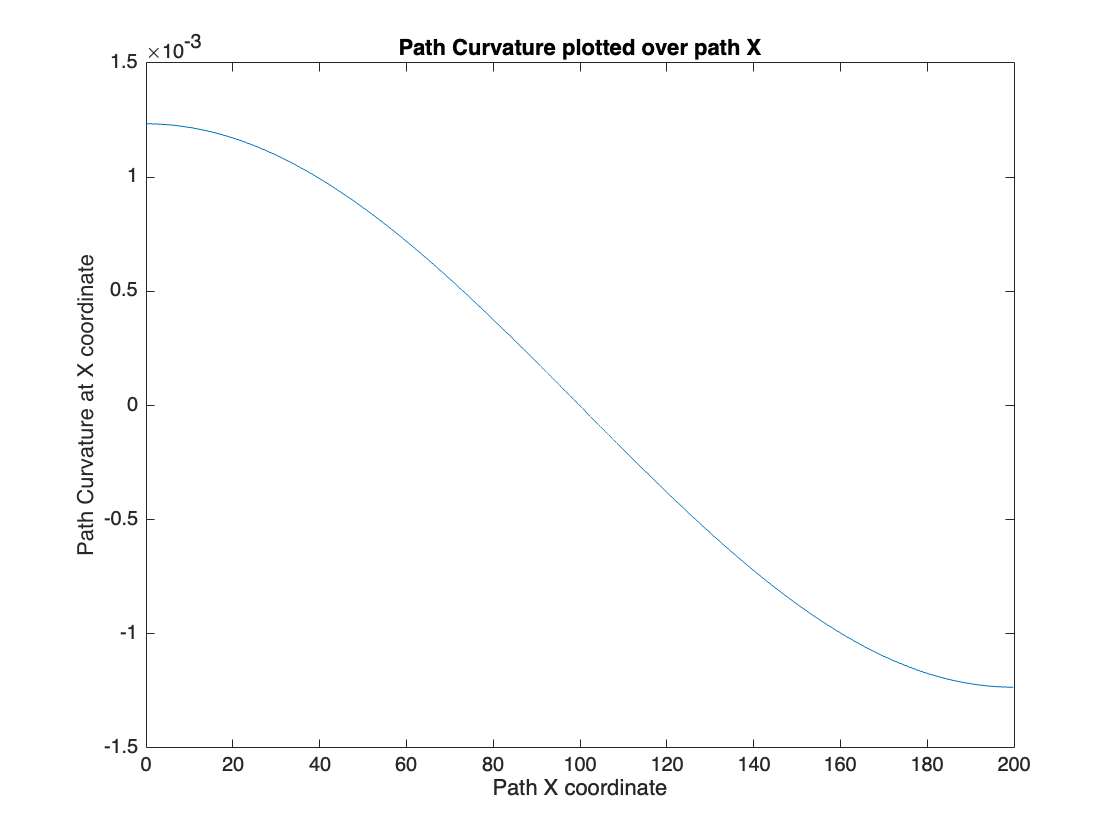

k =     0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012


pathLength = 200.2081

[k pathLength] = getPathCurvature(path)

totalTime = pathLength/Vref;
timeVector = linspace(0,totalTime,length(k));

pathCurvaturesAtTime = [timeVector',k']

pathCurvaturesAtTime =          0    0.0012
    0.0050    0.0012
    0.0100    0.0012
    0.0150    0.0012
    0.0200    0.0012
    0.0251    0.0012
    0.0301    0.0012
    0.0351    0.0012
    0.0401    0.0012
    0.0451    0.0012


# Using the Curvature Values as a Yaw Rate profile, on a yaw controlled model

with a yaw rate PID and feedback control scheme (linear bicycle model)

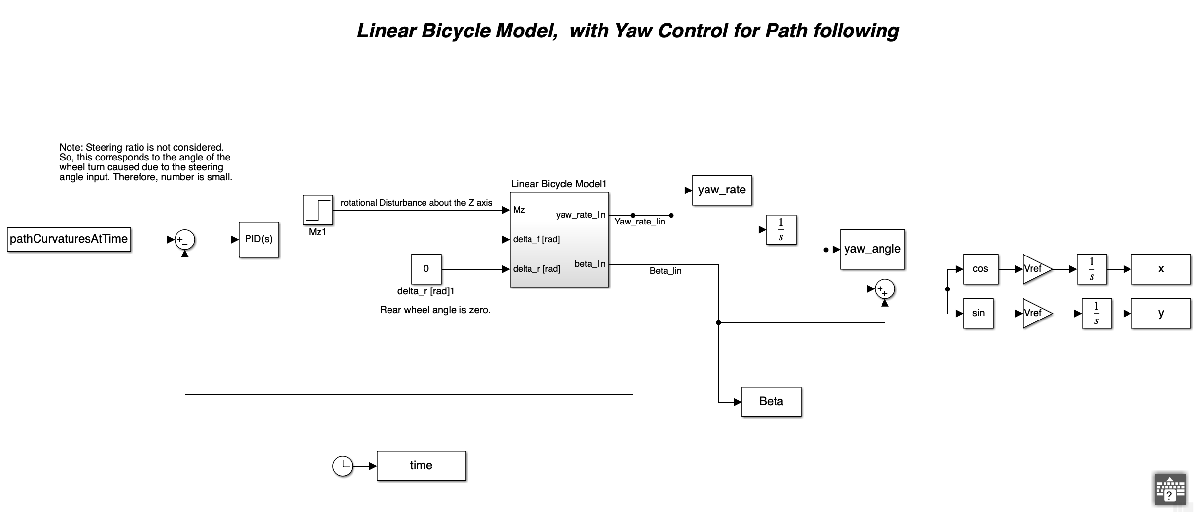

with a disturbance at t = 5

% Testing at Vref = 20
sim('YawPathControl.slx')

Program interruption (Ctrl-C) has been detected.

yaw20 = yaw_rate;
beta20 = Beta;
figure
plot(time,yaw20), hold on, plot(timeVector,k*40), hold off
title('Yaw Rate of the simulated vehicle'), xlabel('Simulation Time (s)'), ylabel('Yaw Rate'), legend('Simulated yaw Rate','Desired Yaw Rate')

The yaw rate profile is well followed by the control system

# Resultant path 

figure 
plot(x,y), hold on, plot(path(:,1),path(:,2),'--k'), title('Path Comparison')
legend('Simulated Path','Desired Path'), xlabel('X'),ylabel('Y')
axis([0 200 0 10]) %0.25 is the max

Run 1: The resultant path is proportional to the desired path, suggesting that tuning or a gain change is needed. 

Run 2: a gain of 40 was added and the path now resembles the desired path

Run 3: Vref increased from 20 to 80, the path has a dY of 5, half of the desired dY, it is still proportional. Further tuning is needed

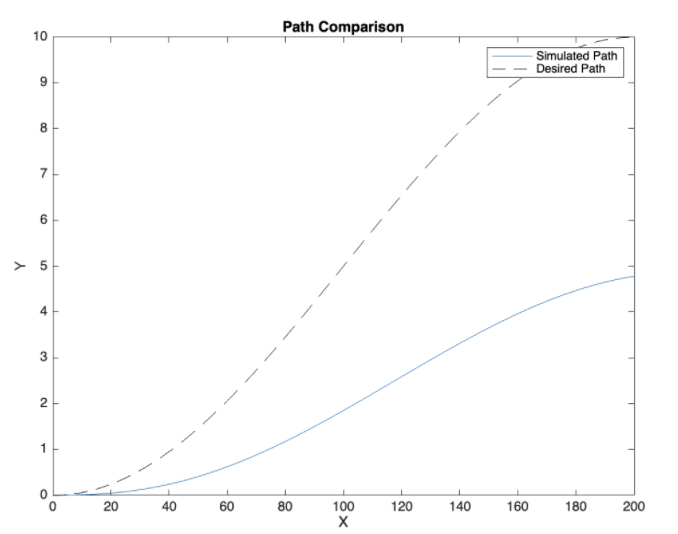

Run 4: Friction is decreased by a factor of 7, Vref is dropped to 20, an overshoot strengthens the idea that further tuning is needed for accurate control

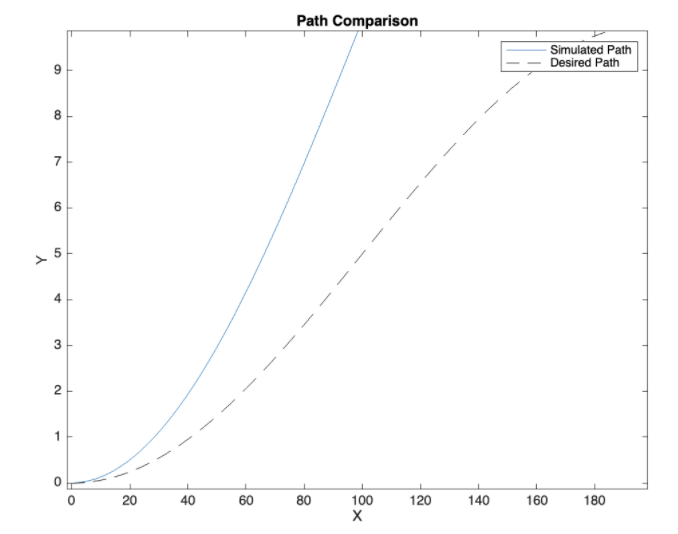

# Brief Conclusion & Future Work

Controlling yaw rate can be an effective means for following a path

This path maneuver could be studied further to yield more precise results for lane changing or parallel parking

# Extra: Plotting Side Slip Angle

%Side Slip angle, Beta, Comparison between models
figure()
plot(time,beta20)
title('Side Slip Angle, Beta, over time'), xlabel('Simulation time (s)'),ylabel('Side Slip angle, Beta')
legend('Linear Model')

# Functions

Path Generation

function path = getLaneChangePath(dX,dY)
    % By Brian Lesko 12/15/22

    % Where the Vehicle Path is defined by dX and dY
    vehicleStart = [0 0];
    vehicleEnd = [dX dY];
    
    % described by a Sin Wave
    period = (vehicleEnd(1)-vehicleStart(1))*2; 
    amplitude = (vehicleEnd(2)-vehicleStart(2))/2; 
    x = 0:0.1:period/2; 
    y = amplitude*sin(2*pi/period*(x-period/4))+amplitude;
    path = [x'+vehicleStart(1) y'+vehicleStart(2)];

    % Plotting
    figure
    plot(path(:,1),path(:,2),'--k'); hold off
    title('Generated Vehicle Maneuver'), xlabel('Longitudinal Distance dX'), ylabel('Lateral Distance dY')
end 

Curvature of path

function [k pathLength] = getPathCurvature(path)
pathy = path(:,2); pathx = path(:,1);
    distance = 0; % initialize 
    for i = 1:1:length(pathy)
        if i<length(pathy)-1
            dydx(i) = (pathy(i+1) - pathy(i))/(pathx(i+1)-pathx(i)); % forward difference method 
            if i<length(pathy)-1
                dydx2(i) =  (pathy(i+2)-2*pathy(i+1)+pathy(i))/(pathx(i+1)-pathx(i))^2;% second order forward differences 
                % Total Travelled Distance
                distance = norm([pathy(i+1),pathx(i+1)]-[pathy(i),pathx(i)]) + distance;
            end 
        end 
    end 
    % path radi
    R = (1+ dydx.^2).^(3/2) ./ (dydx2); %radi of curvature 
    k = 1./R; % the curvature of the path
    pathLength = distance;
    
    plot(pathx(1:length(k)),k)
    title('Path Curvature plotted over path X'),xlabel('Path X coordinate'), ylabel('Path Curvature at X coordinate')
end 